# Practical Assignment 1: Accoustic localisation

Names:Qingyi Ren

NetIDs:5684803

clear; clf; clc; close all;
addpath data\

> 位置：path (第 109 行)
位置: addpath (第 86 行)
位置: addpath (第 49 行)
位置: 

addpath functions\

> 位置：path (第 109 行)
位置: addpath (第 86 行)
位置: addpath (第 49 行)
位置: 

## 1. Calibration

load('calibration.mat')

### a) Measurement errors of each microphone at each sound pulse

**Your text here** (*Please you the equation editor for equations)* **:**

% Your code here !! call your variable meas_errors to avoid getting an error in d)
[xrow,xcol]=size(y_toa);
y_toa_mean=zeros(xrow,xcol);
for i=1:xrow
 y_toa_mean(i,:)=mean(y_toa(i,:)).*ones(1,xcol);
end
meas_errors=y_toa-y_toa_mean;

Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(meas_errors,"1a"))

correct


### b) Measurement bias $b_i$ of each microphone

**Your text here** (*Please you the equation editor for equations)* **:**

% Your code here
biases=zeros(1,xcol)

biases =      0     0     0     0     0     0     0     0


for i=1:xcol
biases(1,i)=mean(meas_errors(:,i));
end

Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(biases,"1b"))

correct


### c) Variance $\sigma_i^2$of the measurement noise $e_i$ of each microphone

**Your text here** (*Please you the equation editor for equations)* **:**

% Your code here
vars=zeros(1,xcol);
for i=1:xcol
vars(1,i)=var(meas_errors(:,i));
end

Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(vars,"1c"))

correct


### d) Visualisation and interpretation of the measurement errors 

Uncomment the code sniplet below.

**Your text here:**

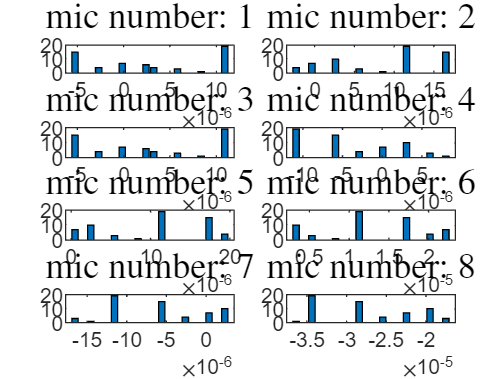

figure(1); clf;
for i = 1:xcol
    subplot(4,2,i);
    [N, l] = hist(meas_errors(:,i),20);
    Wb     = l(2)-l(1); % Bin widths
    Ny     = length(meas_errors(:,i)); % Nr of samples
    bar(l, N);
    title(['mic number: ',num2str(i)],'Interpreter','Latex','Fontsize',14)
end

## 2. Nonlinear least squares

load('experiment1.mat')
load('ground_truth1.mat')

### a) Nonlinear function $f$, and the noise covariance $\Sigma$

**Your text here** (*Please you the equation editor for equations)* **:**

### b) Jacobian

**Your text here** (*Please you the equation editor for equations)* **:**

### c) NLS algorithm

Implement the NLS algorithm to compute the position estimates **in the function templates** at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@f,"2a1"))

correct


disp(testmyresult(@Jacobian,"2a2"))

correct


### d) Computation of position estimates with NLS

Write your code in the box below, using the given initial state vector and maximum number of iterations.

% your code here
th0     = [0.12; 0.8; 70]; % initial state vector
maxiter = 100;             % maximum number of iterations
R       = 10^-10.*eye(3,3);
yk      = y_toa-biases.*ones(137,8);
[th_hat, P_hat]  = NLS(yk,th0,R,maxiter,mic_locations);

无法执行赋值，因为左侧的大小为 3×1，右侧的大小为 3×2。

出错 PracticalAssignment1_RenLong>NLS (第 144 行)
     th_hat(:,j+1)  = th_d_i+th_hat_i;

th_nls           = th_hat%+th0.*ones(size(th_hat));
P_nls            = P_hat;
%error 3-dimension data

### e) Visualisation and interpretation

Uncomment the code below.

**Your text here****:**

figure(2); clf;
plotresults(th_nls(1:2,:),P_nls(1:2,1:2,:),mic_locations',ground_truth);

## 3. Kalman filtering 

### a) KF algorithm

Implement the Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_kf,"3a1"))
disp(testmyresult(@timeupdate_kf,"3a2"))

### b) Computation of position estimates with KF

Write your code in the box below, using the given initial position and intial covariance matrix.

Tune $Q$ and $R_k$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

% your code here
p_0 = th0(1:2,1);
P_0 = zeros(2,2);

%Calculate R_k
% [xrow,xcol]=size(y_toa);
% y_toa_mean=zeros(xrow,xcol);
% for i=1:xrow
%  y_toa_mean(i,:)=mean(y_toa(i,:)).*ones(1,xcol);
% end
% meas_errors=y_toa-y_toa_mean;
% R_k=zeros(xrow,1)
% for i=1:xrow
% R_k(i,1)=var(meas_errors(i,:));
% end
QQ = zeros(2,2);
for i=137
    R_k(:,:,i)= QQ;
end
for i=1:137
R_diff      = y_pos(:,i)-ground_truth(:,i);%when exercise 2 succeed, it needs to be corrected as th_nls(1:2,:)
R_k(:,:,i)  = cov(R_diff');
end
% Calculate Q
Q_diff = y_pos(1:2,2:137)-y_pos(1:2,1:136);%when exercise 2 succeed, it needs to be corrected as th_nls(1:2,:)
Q      = cov(Q_diff');
% y      = th_nls(1:2,:);
y      = y_pos;%when exercise 2 succeed, it needs to be corrected as th_nls(1:2,:)
% [p_kf,P_kf] = KF(p_0,P_0,R_k,Q,y);

### c) Visualisation

Plot the mean and covariance of the **filtered** distribution. Uncomment the plot below.

**Your text here:**

% figure(3); clf;
% plotresults(p_kf,P_kf,mic_locations',ground_truth);

## 4. Extended Kalman fitering

### a) EKF algorithm

Implement the extended Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check wheather your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

%disp(testmyresult(@measupdate_ekf,"4a1"))
%disp(testmyresult(@timeupdate_ekf,"4a2"))

### b) Computation of position estimates with EKF

Tune $Q$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

% your code here


### c) Visualisation

Plot the mean and covariance of the **filtered** distribution.

**Your text here:**

%figure(4); clf;
%plotresults(th_ekf(1:2,:),P_ekf(1:2,1:2,:),mic_locations',ground_truth);

# Copy all your functions below this text before exporting to PDF!! 

## Functions

f

function ftheta = f(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % ftheta            evaluation of f at current state estimate
    c             = 343; % in [m/s]
    ftheta        = zeros(8,1);
    for i=1:8
     ftheta(i,1)  = sqrt((theta(1,1)-mic_locations(i,1)).^2+(theta(2,1)-mic_locations(i,2)).^2)/c+theta(3,1);
    end
end

Jacobian

function dF = Jacobian(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % dF                evaluation of Jacobian at current state estimate
    c    = 343; % in [m/s]
    dF   = zeros(8,3);
    for i=1:8
      df_x = (theta(1,1)-mic_locations(i,1))/(sqrt((theta(1,1)-mic_locations(i,1)).^2+(theta(2,1)-mic_locations(i,2)).^2)*c);
      df_y = (theta(2,1)-mic_locations(i,2))/(sqrt((theta(1,1)-mic_locations(i,1)).^2+(theta(2,1)-mic_locations(i,2)).^2)*c);
      dF(i,:)  = [df_x df_y 1];
    end
end

NLS

function [th_hat, P_hat] = NLS(yk,th_hat0,R,maxiter,mic_locations)
    % INPUT: 
    % y_k               kth measurement
    % th_hat0           initial estimate
    % R                 covariance matrix of measurement noise
    % maxiter           maximum number of iterations 
    % mic_locations     microphone locations
    PP       = zeros(3,3);
    for i=1:size(yk,1)
        P_hat(:,:,i)= PP;
    end
    P_hat(:,:,1)= R;
    th_hat      = zeros(3,size(yk,1));
    th_hat(:,1) = th_hat0;
    W_inv  = inv(R);
    W      = W_inv(1,1);
    th_d      = zeros(3,size(yk,1));
    for j=1:137
      th_hat_i =th_hat(:,j);
      th_d_i   =th_d(:,j);
      P_hat_iI  =inv(P_hat(:,:,j));
     for i=1:maxiter
      ek     = yk(j,:)'-f(th_hat_i,mic_locations);
      F      = Jacobian(th_hat_i,mic_locations);
      K      = inv(P_hat_iI+F'*W*F)*F'*W;
      Id_mat = eye(size(3,3));
      th_d_i   = (Id_mat -K*F)*th_d_i+K*ek;
      P_hat_iI   = P_hat_iI+F'*W*F;
     end
     th_d_i(:,j+1)  = th_d_i;
     th_hat(:,j+1)  = th_d_i+th_hat_i;
     P_hat(:,:,j+1) = inv(P_hat_iI);
    end
    % OUTPUT    
    % th_hat            mean of kth NLS estimate
    % P_hat             covariance matrix of kth NLS estimate
 end


measupdate_kf

 function [p_kf,P_kf] = measupdate_kf(p_k,P_k,R_k,y_k)
    % INPUT
    % p_k   mean of predictive distribution for k|k-1
    % P_k   covariance of predictive distribution for k|k-1
    % R_k   kth measurement noise covariance matrix
    % y_k   kth measurment
    % OUTPUT
    % p_kf  mean of filtering distribution for k|k
    % p_kf  covariance matrix of filtering distribution for k|k
    C=eye(2,2);
    K_k=P_k*C'*inv(C*P_k*C'+R_k);
    p_kf=p_k+K_k*(y_k-C*p_k);
    P_kf=P_k-P_k*C'*inv(C*P_k*C'+R_k)*C*P_k;

end

timeupdate_kf

function [p_kk,P_kk] = timeupdate_kf(p_k,P_k,Q)
    % INPUT
    % p_k   mean of filtering distribution for k|k
    % P_k   covariance matrix of filtering distribution for k|k
    % Q     process noise covariance matrix
    % OUTPUT
    % p_kk  mean of predictive distribution for k+1|k
    % P_kk  covariance of predictive distribution for k+1|k
    p_kk=eye(2,2)*p_k;
    P_kk=eye(2,2)*P_k*eye(2,2)'+Q;
    
end

KF

function [p_kf,P_kf] = KF(p_0,P_0,R,Q,y)
    % INPUT: 
    % p_0       prior mean
    % P_0       prior covariance matrix
    % R         Measurement noise covariance matrices for k = 1,...,137
    % Q         Process noise covariance matrix
    % y         Measurements for k = 1,...,137
    % OUTPUT    
    % p_kf      Mean of the filtered distribution for every k
    % P_kf      Covariance matrix of the filtered distribution for every k
    p_k=p_0;
    P_k=P_0;
    p_kf=zeros(2,137);
    PP       = zeros(2,2);
    for i=1:137
        P_kf(:,:,i)= PP;
    end
    for i=1:137
        [p_k,P_k]   = measupdate_kf(p_k,P_k,R(:,:,i),y(:,i));
        p_kf(:,i)   = p_k;
        P_kf(:,:,i) = P_k;
        [p_kk,P_kk] = timeupdate_kf(p_k,P_k,Q);
        p_k  = p_kk;
        P_k = P_kk;
    end
end


measupdate_ekf

% function [th_ekf,P_ekf] = measupdate_ekf(th_k,P_k,y_k,mic_locations,R)
%     % INPUT
%     % th_k              mean of predictive distribution for k|k-1
%     % P_k               covariance of predictive distribution for k|k-1
%     % y_k               kth measurment
%     % mic_locations     microphone locations
%     % R                 measurement noise covariance matrix
%     % OUTPUT
%     % th_ekf            mean of filtering distribution for k|k
%     % p_ekf             covariance matrix of filtering distribution for k|k
% 
%     c               = 343; %In meters per second
% 
% end

timeupdate_ekf

% function [th_kk,P_kk] = timeupdate_ekf(th_k,P_k,Q)
%     % INPUT
%     % th_k   mean of filtering distribution for k|k
%     % P_k    covariance matrix of filtering distribution for k|k
%     % Q      process noise covariance matrix
%     % OUTPUT
%     % th_kk  mean of predictive distribution for k+1|k
%     % P_kk   covariance of predicted distribution for k+1|k
%     
% 
% end

EKF